# Using a ResNet for Brain Tumor Classification

## 1. Overview of the Problem: Detecting Tumors Using Neural Networks

**This application of neural networks for tumor detection was adapted from** Ismael, S. A. A., Mohammed, A., & Hefny, H. (2020). An enhanced deep learning approach for brain cancer MRI images classification using residual networks. *Artificial intelligence in medicine*, *102*, 101779.

### Summary

**Computer-Assisted Diagnosis** is a deep learning technology aimed to help doctors and radiologists diagnose and classify tumors using imaging data. While humans are really good at doing this task manually, the process is labor intensive. Approaches to facilitate and automate diagnosis would be decrease healthcare costs and time consumed for manual diagnosis.

This paper used **transfer learning** to train a **Residual Network (ResNet)** to classify three kinds of cancers from MRI images. We will go over the essential parts of transfer learning and a high level overview of what a ResNet does. 

## 2. Preliminary theory

### A. Convolutional Neural Networks

### 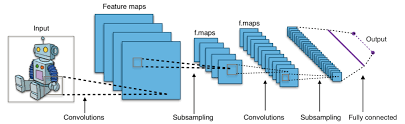

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Typical_cnn.png)

A **Convolutional Neural Network** consists of several additional layers that perform additional computations that are required to capture spatial information from an image. We'll briefy describe what these layers do.

#### Convolution Layer

An image can be represented as a **tensor**: a multi-dimensional matrix in terms of height, width, and the number of colors. For simplicity, we'll only consider gray-scale images, where there is only 1 color dimension. Thus, the image size is two-dimensional, with a height and width.

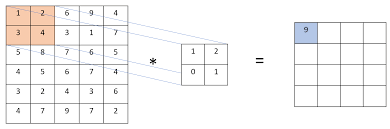

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Convolution.PNG)

In the convolution layer, we're scanning an image (left matrix) using a **filter** - a smaller matrix (middle) that can capture intrinsic features of the image (think edges, shades, etc). **The objective of the neural network is to learn the best set filters that can be generalized across different images to capture intrinsic data structures.** 

While the image is scanned, the area that is being scanned by the filter is beeing combined through **matrix multiplication**. The resulting matrix is called the** feature map** - a condensed representation of the image (right matrix). 

All together, this entire computational process is called a **convolution**.

#### Pooling Layer

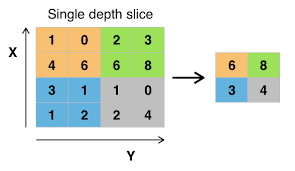

Image taken from [Wikimedia Commons](https://commons.wikimedia.org/wiki/File:Max_pooling.png).

Once we obtain a feature map, the data is condensed even further in the **pooling layer. **The purpose of the pooling layer is to **reduce the computational costs** downstream and **perform feature extraction** for the most important features in an image.   

#### Activation Layer: Rectified Linear Units (ReLUs)

We have seem what the sigmoid activation function does - it transforms data into the range of [0, 1], corresponding to probabilities. Now we will consider a new function: the **Rectified Linear Unit (ReLU)**.

The ReLU floors values to be 0 if the value is negative, or to be that value if positive. A plot of the ReLU distribution is shown below.

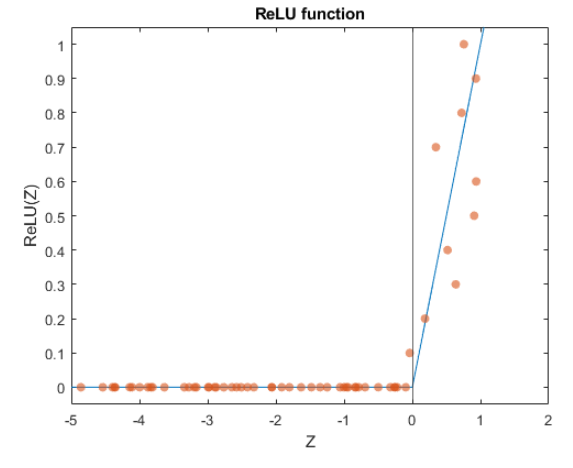

**There are several reasons why the ReLU performs well in neural networks**:

- The gradient during backpropagation is not saturated with a ReLU.

- The ReLU introduces sparsity and is a simple operation to perform, decreasing computational overhead.

#### Fully Connected Layer

From here, we perform a feedforward neural network computation. A schematic of the computation is shown below for review.

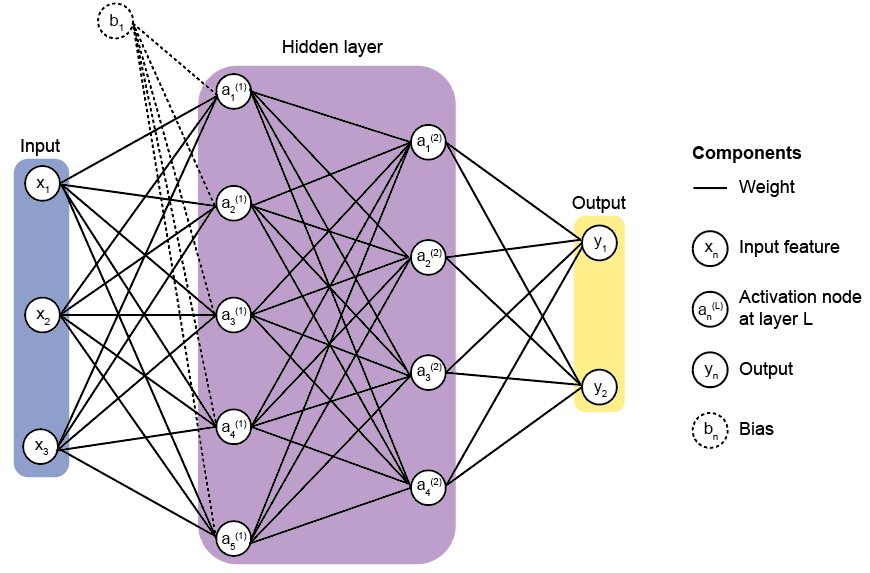

#### Loss Layer 

### B. Transfer learning

### C. Residual Networks

## Load data

% Clear workspace
clear; close all; clc;
 
% Images Datapath – Please modify your path accordingly 
datapath='D:/Data/Brain_img/dataset';
 
% Image Datastore
imds = fileDatastore(fullfile(datapath), ...
                   'ReadFcn', @load, ...
                   'FileExtensions','.mat');

% Determine the split up
total_split=countEachLabel(imds)

## Visualize images

% Number of Images
num_images=length(imds.Labels);

% Visualize random images
perm=randperm(num_images,6);
figure;
for idx=1:length(perm)
    
    subplot(2,3,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
    
end

## K-fold validation

% Number of folds
num_folds=10;

% Loop for each fold
for fold_idx=1:num_folds
    
    fprintf('Processing %d among %d folds \n',fold_idx,num_folds);
    
   % Test Indices for current fold
    test_idx=fold_idx:num_folds:num_images;

    % Test cases for current fold
    imdsTest = subset(imds,test_idx);
    
    % Train indices for current fold
    train_idx=setdiff(1:length(imds.Files),test_idx);
    
    % Train cases for current fold
    imdsTrain = subset(imds,train_idx);
 
    % ResNet Architecture 
    net=resnet50;
    lgraph = layerGraph(net);
    clear net;
    
    % Number of categories
    numClasses = numel(categories(imdsTrain.Labels));
    
    % New Learnable Layer
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    % Replacing the last layers with new layers
    lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
    newsoftmaxLayer = softmaxLayer('Name','new_softmax');
    lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);
    
    
    % Preprocessing Technique
    imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);
    
    % Training Options, we choose a small mini-batch size due to limited images 
    options = trainingOptions('adam',...
        'MaxEpochs',30,'MiniBatchSize',8,...
        'Shuffle','every-epoch', ...
        'InitialLearnRate',1e-4, ...
        'Verbose',false, ...
        'Plots','training-progress');
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    
    % Training
    netTransfer = trainNetwork(auimds,lgraph,options);
    
    % Resizing all testing images to [224 224] for ResNet architecture   
    augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
    % Testing and their corresponding Labels and Posterior for each Case
    [predicted_labels(test_idx),posterior(test_idx,:)] = classify(netTransfer,augtestimds);
    
    % Save the Independent ResNet Architectures obtained for each Fold
    save(sprintf('ResNet50_%d_among_%d_folds',fold_idx,num_folds),'netTransfer','test_idx','train_idx');
    
    % Clearing unnecessary variables 
    clearvars -except fold_idx num_folds num_images predicted_labels posterior imds netTransfer;
    
end

## Validation

% Actual Labels
actual_labels=imds.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels')
title('Confusion Matrix: ResNet');